# PODSTAWY PROGRAMOWANIA W JĘZYKU MATLAB

## Pętle i instrukcje warunkowe

Opracował: K. Król

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Rigth"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

W MATLAB mamy standardowe pętle i instrukcje znane w większości języków programowania. Są to pętle ***for*** i ***while*** oraz instrukcje warunkowe ***if*** i ***switch***. Ich działanie w większości przypadków jest intuicyjne, ale są pewne niuanse związane z przystosowaniem MATLABA do działania na macierzach/wektorach.

Zaczniemy od pętli ***for*** i ***while***. Obie pętle wykonują się wielokrotnie na podstawie dostarczonego warunku. Oprócz oczywistych różnic w zapisie warunku końca pętli warto zwrócić uwagę, że **pętla *****while***** sprawdza warunek przed wykonaniem kodu, więc kod wewnątrz pętli może się nie wykonać ani razu. Natomiast pętla *****for***** sprawdza warunek na końcu kodu, więc kod w pętli *****for***** musi wykonać się przynajmniej raz.**

### **Budowa i działanie pętli for**

Ogólna budowa pętli ***for*** pokazana jest poniżej:

**for index = wektor_wartości**

**    <komendy> **

**end**

Pętlę zaczynamy od słowa kluczowego 'for', wraz z zapisem warunku wykonania, a kończymy słowem kluczowym 'end'. Pomiędzy tymi słowami kluczowymi znajduje się kod wewnątrz pętli. 

**Zwróć uwagę, że w MATLAB ze względu na przystosowanie do operacji macierzowych w rzeczywistości jest to pętla *****foreach*****, a nie klasyczna pętla *****for ***(więcej informacji o pętli*** foreach ***znajdziesz [tutaj](https://pl.wikipedia.org/wiki/P%C4%99tla_foreach)). 

Różnica jest subtelna, ale można ją wykorzystać do usprawnienia pisania kodu i ominięcia problemu indeksowania wektorów. Na czym to polega? Przeanalizuj poniższy kod, który pokazuje, jak można zaimplementować pętle ***for*** w sposób analogiczny do większości języków programowania:

% W pętli występuje indeks i, który przyjmuje wartości od jeden do n, gdzie
% n jest liczbą elementów wektora h. W każdej iteracji i zwiększa się o 1.

h = [1e2 1e3 1e4 1e5 1e6 1e7];

for i=1:1:numel(h) 
    fprintf("Indeks: %d, wartość: %e\n",i,h(i));
end

Indeks 1, wartosc 1.000000e+02
Indeks 2, wartosc 1.000000e+03
Indeks 3, wartosc 1.000000e+04
Indeks 4, wartosc 1.000000e+05
Indeks 5, wartosc 1.000000e+06
Indeks 6, wartosc 1.000000e+07


Jest to kod, w którym pętla for iteruje po indeksach tablicy i indeksy są wykorzystywane do wyłuskania z tablicy konkretnych elementów. Zwróć jednak uwagę na definicję pętli for w MATLAB, a konkretnie na początek pętli.

for i=1:1:numel(h)
    
end

Następuje w nim:

- stworzenie wektora od 1 z krokiem 1 do liczby elementów wektora h. Gdybyśmy chcieli zapisać tę operację jawnie napisalibyśmy tak:

I=[1:1:numel(h)]
 

- Następnie ten wektor jest podawany do pętli ***for***, która w kolejnych iteracjach pobiera z niego kolejne elementy i podstawia pod zmienną 'i', równie dobrze moglibyśmy całą tę pętlę zapisać:

I=[1:1:numel(h)];
for i=I 
    fprintf("Wartość kolejnego elementu wektora I: %d, wartość odpowiedniego elementu wektora h: %e\n",i,h(i));
end

Wartość kolejnego elementu wektora I: 1, wartość odpowiedniego elementu wektora h: 1.000000e+02
Wartość kolejnego elementu wektora I: 2, wartość odpowiedniego elementu wektora h: 1.000000e+03
Wartość kolejnego elementu wektora I: 3, wartość odpowiedniego elementu wektora h: 1.000000e+04
Wartość kolejnego elementu wektora I: 4, wartość odpowiedniego elementu wektora h: 1.000000e+05
Wartość kolejnego elementu wektora I: 5, wartość odpowiedniego elementu wektora h: 1.000000e+06
Wartość kolejnego elementu wektora I: 6, wartość odpowiedniego elementu wektora h: 1.000000e+07


Teraz w wektorze I znajdują się liczby, które traktujemy jak indeksy, ale przecież nie są one nam potrzebne do wypisania zawartości wektora 'h'. Można bowiem podać do pętli sam wektor 'h':

for i=h
    fprintf("Wartość kolejnego elementu wektora h: %d\n",i);
end

Wartość kolejnego elementu wektora h: 100
Wartość kolejnego elementu wektora h: 1000
Wartość kolejnego elementu wektora h: 10000
Wartość kolejnego elementu wektora h: 100000
Wartość kolejnego elementu wektora h: 1000000
Wartość kolejnego elementu wektora h: 10000000


Pętla działa na zmiennej 'i', ale tym razem w kolejnych iteracjach podstawiane pod nią będą kolejne elementy wektora h. Indeksy są nam w tym wypadku niepotrzebne. Odbywa się to z pewną utratą wydajności kodu, ale dla niewielkich wektorów jest ona pomijalna. W trakcie realziacji przedmiotu WNUM, zaleca się korzystanie z tej metody wszędzie tam, gdzie jest to możliwe.

### Budowa i działanie pętli while

Pętla ***while ***działa w MATLAB w sposób klasyczny. Jej ogólna postać widoczna jest poniżej. Pętlę zaczynamy słowem kluczowym ‘while, po którym następuje podanie warunku, a kończymy słowem kluczowym ‘end.

**while <warunek> **

**    <komendy > **

**end**

%klasyczne działanie pętli while
n = 10;
f = n;

while n > 1     %słowo kluczowe + warunek
    n = n-1;
    f = f*n;
end             %słowo kluczowe - koniec pętli
disp(['n! = ' num2str(f)])

 

W niektórych zastosowaniach trzeba pamiętać o tym, że warunek pętli while jest sprawdzany przed wykonaniem iteracji, zaś warunek pętli for jest sprawdzany po wykoaniu iteracji.

### Instrukcje przerwania/opuszczenia pętli

W normalnych okolicznościach cały kod w pętli musi się wykonać, aby przejść do następnej iteracji. Można jednak wymusić przerwanie wykonywania kodu i przeskoczyć bezpośrednio do następnej iteracji pętli za pomocą komendy ***'continue'***:

fid = [1 2 3 4 5 6 7 8 9]

fid =      1     2     3     4     5     6     7     8     9


count = 0;
while count<numel(fid)
    count = count + 1;
    element = fid(count);
    if mod(element,3)==0
        continue
    end
    fprintf('Element: %d\n',element);
end

Element: 1
Element: 2
Element: 4
Element: 5
Element: 7
Element: 8


Elementy których wartość była podzielna przez 3 nie zostały wyświetlone, ale wszystkie operacje przed komendą ***continue*** zostały wewnątrz pętli na tych elementach wykonane.

Można też przerwać działanie pętli w ogóle i przejść do kodu poza pętlą poprzez komendę ***'break'***. W przeciwieństwie do komendy ***'continue'*** przerwane jest działanie całej pętli:

fid = [1 2 3 4 5 6 7 8 9]

fid =      1     2     3     4     5     6     7     8     9


count = 0;
while count<numel(fid)
    count = count + 1;
    element = fid(count);
    if mod(element,3)==0
        break;
    end
    fprintf('Element: %d\n',element);
end

Element: 1
Element: 2


**Oba mechanizmy działają tak samo w pętlach for i while!**

### **Wychodzenie z nieskończonej pętli i przerwanie wykonywania skryptu**

W trakcie testowania kodu, może się zdarzyć, że MATLAB utknie w pętli nieskończonej. Podobny problem może się również wydarzyć, jeżeli działanie kodu zablokuje nam w inny sposób interpretator poleceń - np. w skutek błędu, MATLAB będzie wypisywał na ekran jakąś bardzo dużą macierz z milionami elementów. 

Generalnie interpretator poleceń, kiedy jest gotowy do przyjęcia kolejnej komendy zgłasza to na konsoli wyświetlając znak zachęty, który wygląda tak:

Jeżeli go nie widać, to interpretator realizuje jakieś polecenie. Może ono nie wypisywać żadnych danych na konsolę i wtedy MATLAB wygląda jakby się zawiesił.

Użytkownik może zawsze przerwać działanie aktualnie przetwarzanego kodu poprzez naciśnięcie na klawiaturze kombinacji **Ctrl+C**.

% Skopiuj poniższy kod do konsoli i uruchom
% Zobacz, że w trakcie działania kodu nie jest widoczny znak zachęty
% Przerwij działanie nieskończonej pętli kombinacją Ctrl+C

i=0;
while(1)
    i=i+1;
end

**UWAGA! **

**MATLAB kolejkuje zadania. Zatem jeżeli będzie miał zakolejkowane kolejne zadanie, to po przerwaniu aktualnie wykonywanej komendy zacznie wykonywać następną z kolejki. Potencjalnie ten sam wadliwy kod (np. gdy kilkukrotnie klikniemy przycisk RUN). **Dlatego najlepiej użyć Ctrl+C kilka razy.

### Budowa i działanie instrukcji warunkowej if ... then ... else

W MATAB mamy również dostępną standardową instrukcję warunkową ***if***. Szablon składni podany jest poniżej:

**if <*****wyrażenie>***

***    <komendy>*** 

**elseif<*****wyrażenie > *****(opcjonalnie)**

***    < komendy >***

**else                         (opcjonalnie)**

***    < komendy >***

**end**

Zaczyna się ona słowem kluczowym 'if', po którym następuje sekcja kodu. Zasięg instrukcji kończymy słowem kluczowym 'end'. To wyrażenie w działaniu niczym się nie różni od innych języków programowania. 

% Przykład zastosowania instrukcji if z warunkami łączonymi za pomocą
% operatorów logicznych:
%   relop      - logiczne AND                                           &&     
%   relop      - logiczne OR                                            ||     
%   and        - logiczne AND wykonane po elementach wektora            &      
%   or         - logiczne OR wykonane po elementach wektora             |      
%   not        - logiczne NOT                                           ~      
% więcej informacji wpisz komendę w konsolę 'doc &&'.

x = 10;
minVal = 2;
maxVal = 6;

if (x >= minVal) && (x <= maxVal)
    disp('Wartość w wyspecyfikowanym zakresie.')
elseif (x > maxVal)
    disp('Wartość przekracza maksimum.')
else
    disp('Wartość ponizej minimum.')
end

Wartość przekracza maksimum.


### Budowa i działanie instrukcji warunkowej switch ... case ... otherwise

Innym rodzajem instrukcji warunkowej jest instrukcja ***switch ... case ... otherwise***. Również ta instrukcja działa tak jak w innych języka oprogramowania, jej składnia przedstawiona jest poniżej:

**switch <zmienna*****>***

***case *****<*****wyrażenie >***

***    < komendy >***

***case *****<*****wyrażenie >***

***    < komendy >***

***...***

**otherwise**

***    < komendy >***

**end**

Przykład działania instrukcji warunkowej ***case***:

n = input('Wpisz liczbę: ');
%UWAGA! "input" jest wczytywany z konsoli, zatem to tam trzeba wpisać liczbę

switch n
    case -1
        disp('minus jeden')
    case 0
        disp('zero')
    case 1
        disp('plus jeden')
    otherwise
        disp('inna liczba')
end

inna liczba


## Uniwersalny szablon kodu na laboratorium WNUM:

Większość zadań w trakcie laboratorium będzie polegało na badaniu właściwości metody numerycznej w zależości od przyjmowanych parametrów (np. błąd metody w funkcji zmieniającego się kroku, punktu startowego, rzędu itp). Można zatem powiedzieć, że istnieje szablon kodu, który znajdzie zastosowanie w przeważającej liczbie zadań. Konstrukcja tego szablonu przedstawia się następująco (nawiasem mówiąc po uogólnieniu jest to szablon uniwersalny dla znacznej części praktycznych zagadnień inżynierskich):

1.    Inicjalizacja danych wejściowych,

2.    Pętla po kolejnych wartościach zmienianego parametru - w trakcie WNUM zazwyczaj w niej będą wykonywane następujące operacje:

       a) wykonanie obliczeń z użyciem jakiejś metody numerycznej, zapisanie wyniku,

       b) obliczenie błędu rozwiązania, np. poprzez odjęcie od uzyskanego wyniku wartości prawdziwej znanej z rozwiązania analitycznego,

 3.    Po zakończeniu pętli należy wyrysować, bądź wypisać, wpływ danego parametru na badaną             właściwość (np. błąd globalny w zależności od długości kroku), oraz bazując na wiedzy z wykładu wyjaśnić obserwowane zjawiska.

O ile to możliwe, zalecamy tworzenie tego szablonu w pętli bez indeksowania (z wykorzystaniem operatora konkatenacji i MATLAB'owej definicji pętli for), bo to pozwala uniknąć częstych problemów z indeksowaniem elementów pętli, hardkodowaniem wartości, obliczaniem długości wektorów itp.

Ponieżej przykład poprawnego szablonu:

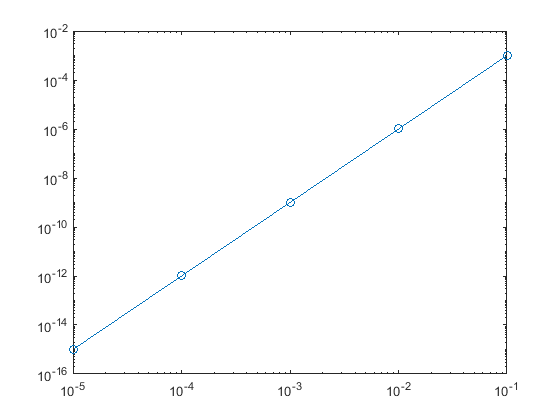

% ... (inicjalizacja jakichś wartości i parametrów metody/zadania)
wynikPrawdziwy = 0; %wyznaczony na podstawie obliczeń analitycznych
% nasz parametr nazywa się h - zazwyczaj oznaczamy tak długość kroku metody

h = [1e-1 1e-2 1e-3 1e-4 1e-5];

blad = []; %definicja wektora konieczna przy użyciu konkatenacji (łączenia) wewnątrz pętli
for i=h
    wynik = i.^3;       %i^3 dla przykładu - tutaj będzie implementacja jakiejś metody
    blad_w_itej_iteracji = wynik-wynikPrawdziwy;
    blad = [blad blad_w_itej_iteracji];  % dzięki operatorowi konkatenacji dokładamy najnowszy 
                                         % wynik na koniec wektora, a
                                         % dzięki zapisaniu pętli for żeby
                                         % iterowała po wektorze h zawsze
                                         % mamy tyle elementów ile potrzeba
                                         % do rysowania szukanej zależności
end

loglog(h, blad,'-o');  %typ wykresu należy dobrać tak, aby prezentowane zależności były dobrze widoczne

Oczywiście można (a być może w niektórych przypadkach będzie to konieczne) zaimplementować to samo w pętli z bezpośrednim indeksem iteracji, jednak trzeba wtedy zachować ostrożność, żeby nie popełnić popularnych (i trudnych do wychwycenia) błędów:

% ... (inicjalizacja jakichś wartości i parametrów metody/zadania)
wynikPrawdziwy = 0;
% nasz parametr nazywa się h - zazwyczaj oznaczamy tak długość kroku metody

h = [1e-1 1e-2 1e-3 1e-4 1e-5];

blad = zeros(numel(h)); %definicja wektora przed pętlą nie jest w tym wypadku konieczna,
                        %ale pozwala przyspieszyć działanie programu (przy
                        %dużych wektorach).
                        %Należy unikać sztywnego definiowania rozmiaru
                        %(hardcodowania) wektora oraz z rozmysłem używać
                        %funkcji length() lub numel() - vide uwagi z rozdz.
                        %operatory tablicowe.
for i=1:numel(h)            %Należy unikać sztywnego definiowania warunku pętli
                            %(hardcodowania) oraz z rozmysłem używać
                            %funkcji length() lub numel() - vide uwagi z rozdz.
                            %operatory tablicowe.
    wynik = h(i).^3; % Tutaj powinna być implementacja jakiejś metody
    blad(i) = wynik-wynikPrawdziwy;  %mogą pojawić się "dziwne" wyniki, jeżeli nie wszystkie elementy zdefiniowanego przed pętlą wektora zostaną nadpisane.
end

loglog(h, blad,'-o'); %w tym przypadku wykreślamy wynik na skali loglog, bowiem zarówno argumenty, jak i odpowiadający im "blad" zmieniają się o wiele rzędów wielkości.
 

Warszawa, 27.02.2021 r.                                                                                                           **© **K. Król

Sem. 21L